# matlab2word

## Library description

This is a library that allows you to transfer your calculations into MS Word template file. It might be useful when you have a report template which has specific formatting and requires some calculations.

MS Wors has good tools for formatting, but its VBA scripting language is realy poor in calculations. Otherwise MatLAB is excellent for calculattions and data processing. There are some tools for report generation in MatLAB too. These tools can create a report through coding which is a bit counterintuitive. My library allows to format report file in Word, do calculations in MatLAB and combine the result into one file.

## Word document preparation 

Create new Word file and put here id strings (as it shown on picture below) which will be replaced by calculated data. Id strings should be concluded in triangle brackets `<>`. Take into accouunt that id strings in equation area should be typed without *italic* font style, it is important for finding this strings.

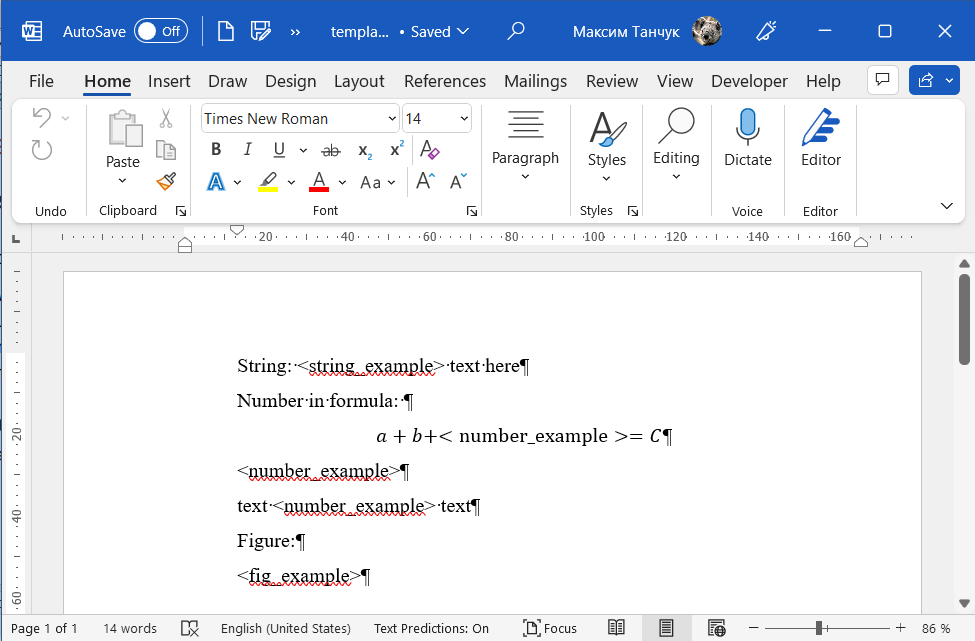

After creating your report template save it with **.docx** extention and fully close your Word application (including windows with other files).

## Example of calculations

Let your calculations look like this.

test_string = 'Hello';
test_num = 0.00000000000000000386-0.000000000013i;
% Create test figure
x = (-4*pi):(8*pi/1000):(4*pi);
f_x_sin_x = sin(x);
fig1 = figure(1); % Here you need to stote the figure handler
plot(x, f_x_sin_x);

Here you have typical string, number and figure examples. Let's transfer them into Word.

## Transfering to Word

First you have to create an instance of your Word document to get an acces to it. Type:

m2w = matlab2word();

This command asks you to select a template file and opens int. Alternatively you can specify your file name by code with `matlab2word` function argument like this:

% m2w = matlab2word('template.docx');

By default MatLAB uses *dot* as a decimal separator, you can change in to *comma* with the command:

m2w.SetDecimalSeparator('comma');

Then just replace your id strings by calculated data using function:

m2w.Replace('string_example', test_string);
m2w.Replace('number_example', test_num);
m2w.Replace('fig_example', fig1);

Replacement functions tkes 2 arguments. First is id string from Word document, second is variable in MatLAB. Replacement commands might take some time to run.

At the end save your report by command:

m2w.Save();

You wil be asked to select a location for output file.